# PROJECT 4 MPSK(M-ARY) 



x_db = 0:0.1:25; % SNR Es/NO
x = 10.^(x_db/10); % db -> linear
M = 8;

low_bound = qfunc(sin(pi/M)*sqrt(2*x));
upper_bound = 2*qfunc(sin(pi/M)*sqrt(2*x));

figure(1)
semilogy(x_db,upper_bound,'b','DisplayName','Upper Bound');
hold on
semilogy(x_db,low_bound,'r','DisplayName','Lower Bound');
title('Symbol Probability Curves')
ylabel('P[Error]')
xlabel('Eb/No(dB)')
legend show

x1 = find(x_db == 5);
x2 = find(x_db == 10);
x3 = find(x_db == 15);
y1U = upper_bound(x1);
y1L = low_bound(x1);
y2U = upper_bound(x2);
y2L = low_bound(x2);
y3U = upper_bound(x3);
y3L = low_bound(x3);

n = 10^5; % number of samples
Es= 1; 

si1=zeros(1,M);
si2=zeros(1,M);

for a = 1:M
    si1(a) = sqrt(Es)*cos(((a-1)*2*pi)/M);
    si2(a) = sqrt(Es)*sin(((a-1)*2*pi)/M);
end 
figure(2)
SNRs = [5 10 15];
dataTx = randi([1,8],[1,n]);
i = 1;
ser = zeros(1,length(SNRs));
for snr_db = SNRs
    snr = 10^(snr_db/10);
    sigma = sqrt((Es/snr)/2);
    
    r1 = zeros(1,n);
    r2 = zeros(1,n);
    dataRx = zeros(1,n);
    for v = 1:n
        w1 = normrnd(0,sigma);
        w2 = normrnd(0,sigma);
  
        r1(v) = si1(dataTx(v))+w1;
        r2(v) = si2(dataTx(v))+w2;
        d = zeros(1,M); % distance
        for z = 1:M
            d(z) = (r1(v) - si1(z))^2 + (r2(v) - si2(z))^2;
        end
        dataRx(v) = find(min(d)==d); 
    end
    nod = length(dataTx); %number of data points
    noe = nnz(abs(dataTx - dataRx)); % number of non-zero elements which are incorrect
    ser(i) = noe/nod % SER, Symbol Error Rate
    i=i+1;
end

ser =     0.3339         0         0


ser =     0.3339    0.0875         0


ser =     0.3339    0.0875    0.0024


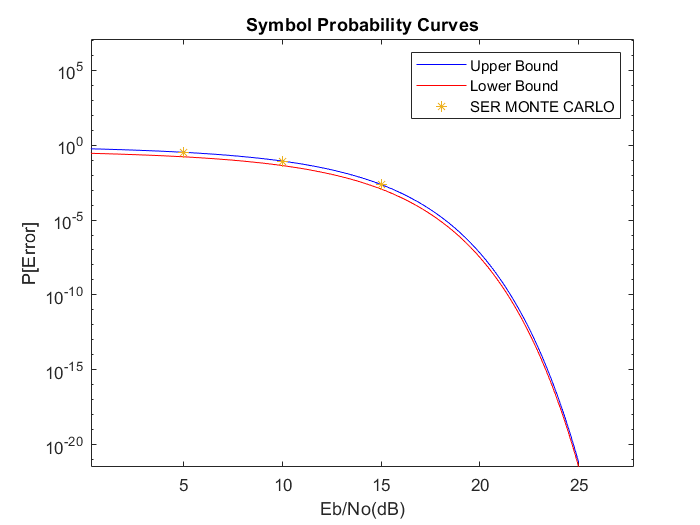


figure(1)
semilogy(SNRs,ser,'*','DisplayName','SER MONTE CARLO')

xlim([0.3 27.8])
ylim([0 12517258])
hold off

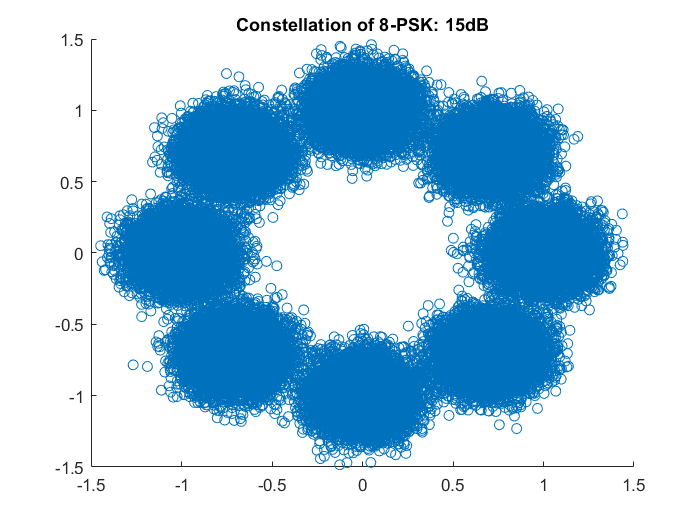

figure(2)

scatter(r1,r2)
title('Constellation of 8-PSK: 15dB')

[Discussion]

    The symbol error rate (SER) from the  Monte Carlo simulation was in between the bounds of the symbol probability

curve approximated in part 1, however, the symbol errors seem to fall closer to the upper bounds rather than the lower bounds

on the symbol probability curve. This is probably due to the lack of SNRs tested in the Monte Carlo simulations.

    An interesting observation is that the symbol errors form the Monte Carlo simulations somtimes fall above the upper bounds,

I believe this is due to the added noise energy, which increasses the distance from region 1 and 2 which the upper bound takes 

into account as shown in the equations below.  

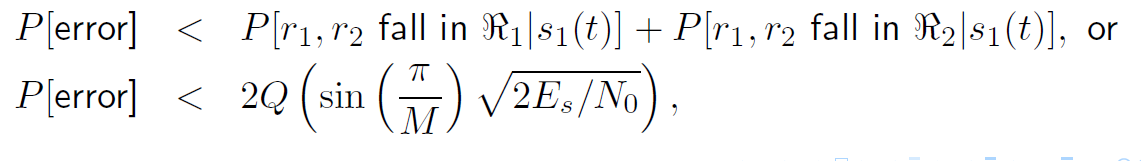

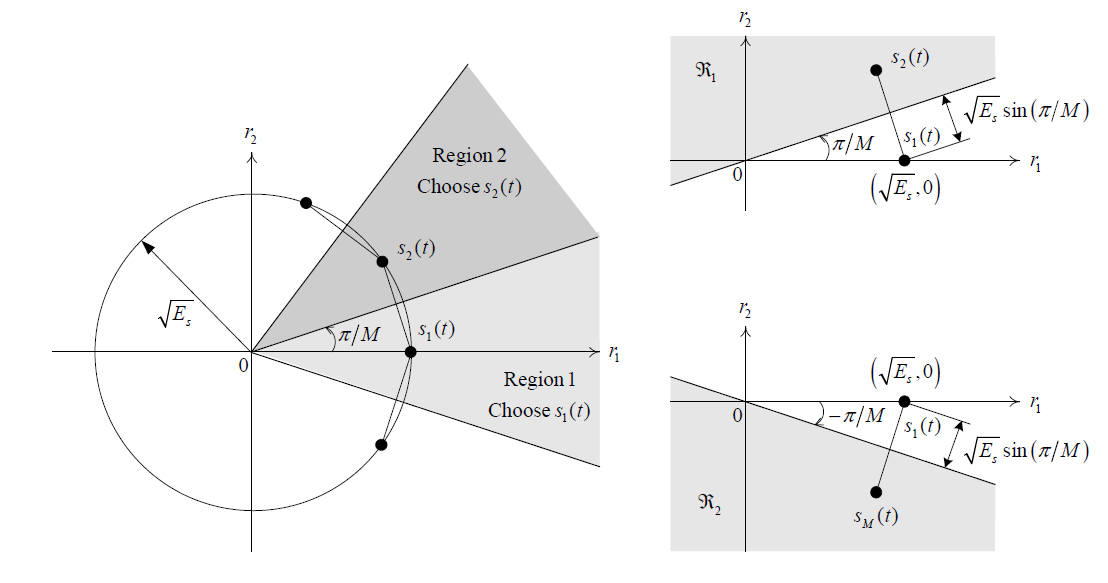

From repeated testing if we decrease Es when just calulating sigma, to 90 percent of its 

value from when the constellations were caluclated, the SER will fall closer to the lower bounds. However, this is a observation 

of a limited number of tests runs, it is more probable that if the test was repeated multiple times the results  will be more evenly distributed

between the upper and lower bounds.

Overall, the results from both the symbol probability curve and Monte Carlo simulations seem to be consistant with each other.